% electrical constants and derived quantities for typical 
% mammalian dendrite

% Dimensions of compartments

d1 = 75e-4; 			% cm
d21 = 30e-4; 			% cm
d22 = 15e-4; 			% cm
%d21 = 47.2470e-4;       % E9 cm
%d22 = d21;               % E9 cm

l1 = 1.5;			% dimensionless
l21 = 3.0;			% dimensionless
l22 = 3.0;			% dimensionless

% Electrical properties of compartments

Rm = 6e3;			% Ohms cm^2
Rc = 90;			% Ohms cm
Rs = 1e6;			% Ohms

c1 = 2*(Rc*Rm)^(1/2)/pi;

rl1 = c1*d1^(-3/2);		% Ohms
rl21 = c1*d21^(-3/2);		% Ohms
rl22 = c1*d22^(-3/2);		% Ohms


% Applied current

iapp = 1e-9; 	% Amps

% Coefficient matrices

A = [1 -1 0 0 0 0;
     0 0 exp(-l21) exp(l21) 0 0;
     0 0 0 0 exp(-l22) exp(l22);
     exp(-l1) exp(l1) -exp(-l1) -exp(l1) 0 0;
     0 0 exp(-l1) exp(l1) -exp(-l1) -exp(l1);
     -exp(-l1) exp(l1) rl1*exp(-l1)/rl21 -rl1*exp(l1)/rl21 rl1*exp(-l1)/rl22 -rl1*exp(-l1)/rl22];

b = [rl1*iapp 0 0 0 0 0]';

## **Question 03**

x=A\b;
display(x);

x =     0.0007
    0.0000
    0.0011
   -0.0000
    0.0011
   -0.0000


As the result


$$A_1 = 0.0007\\
A_2=0.0000\\
A_{21}=0.0011\\
B_{21}=-0.0000\\
A_{22}=0.0011\\
B_{21}=-0.0000\\$$


## Question 04

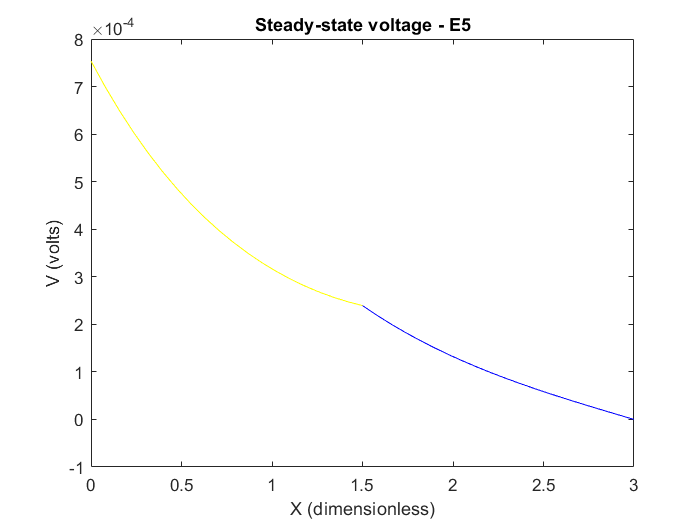

y1 = linspace(0, l1, 20);
y21 = linspace(l1, l21, 20);
y22 = linspace(l1, l22, 20);
v1 = x(1)*exp(-y1) + x(2)*exp(y1);
v21 = x(3)*exp(-y21) + x(4)*exp(y21);
v22 = x(5)*exp(-y22) + x(6)*exp(y22);
plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
xlabel('X (dimensionless)');
ylabel('V (volts)');
title('Steady-state voltage - E5');

Plot of $V_{21}(X)$ and the plot of $V_{22}(X)$ seem to be identical. even $A_{21}=A_{22} $ and $B_{21}=B_{22}$ as the results.

So the steady state voltage profile in the two daughter branches are equal through the two branches.

## Question 05

A_a=A;
b_a=b;

(a) ${\left(\frac{d}{\mathrm{d}X}V_{21} \right)}_{X=L_{21} } =0$ ; 


$$-A_{21} e^{-L_{21} } +B_{21} e^{-L_{21} } =0\;\;\;\;------\to \left({3^{\prime } }^{\prime } \right)$$


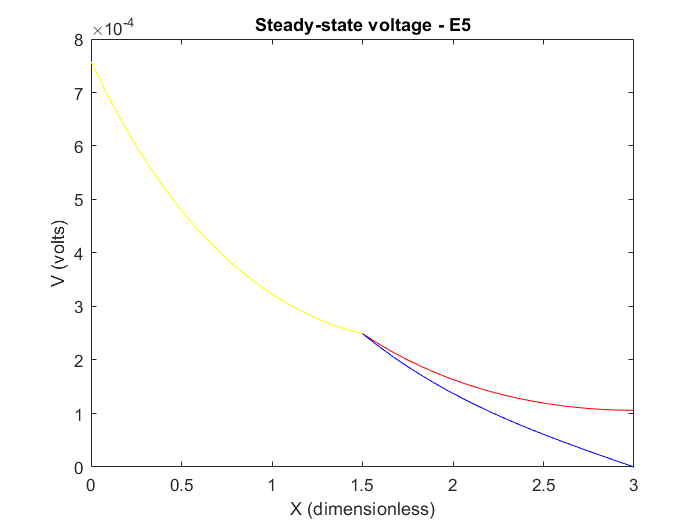

A_a(2,:)=[0 0 -exp(-l21) exp(l21) 0 0];
x_a=A_a\b;

y1 = linspace(0, l1, 20);
y21 = linspace(l1, l21, 20);
y22 = linspace(l1, l22, 20);
v1 = x_a(1)*exp(-y1) + x_a(2)*exp(y1);
v21 = x_a(3)*exp(-y21) + x_a(4)*exp(y21);
v22 = x_a(5)*exp(-y22) + x_a(6)*exp(y22);
plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
xlabel('X (dimensionless)');
ylabel('V (volts)');
title('Steady-state voltage - E5');

(b) ${\left(\frac{d}{\mathrm{d}X}V_{22} \right)}_{X=L_{22} } =0$ ;


$$-A_{22} e^{-L_{22} } +B_{22} e^{-L_{22} } =0\;\;\;\;------\to \left(4^{\prime \prime } \right)$$


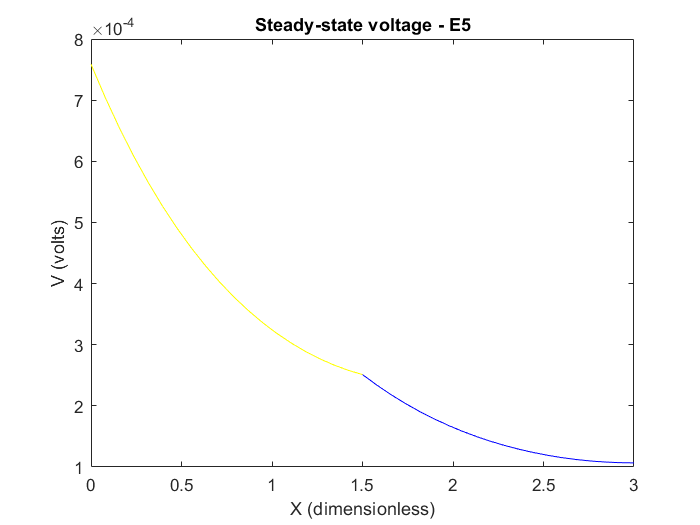

A_a(3,:) = [0 0 0 0 -exp(-l22) exp(l22)];
x_a=A_a\b;

y1 = linspace(0, l1, 20);
y21 = linspace(l1, l21, 20);
y22 = linspace(l1, l22, 20);
v1 = x_a(1)*exp(-y1) + x_a(2)*exp(y1);
v21 = x_a(3)*exp(-y21) + x_a(4)*exp(y21);
v22 = x_a(5)*exp(-y22) + x_a(6)*exp(y22);
plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
xlabel('X (dimensionless)');
ylabel('V (volts)');
title('Steady-state voltage - E5');

(c) ${\left(\frac{d}{\mathrm{d}X}V_1 \right)}_{X=0} =0$ ;   $-A_1 +B_1 =0-----\to \left({1^{\prime } }^{\prime } \right)$

        ${\left(\frac{d}{\mathrm{d}X}V_{21} \right)}_{X=L_{21} } ={\left(r_i \lambda_c \right)}_{21} I_{\textrm{app}}$ ;    $-A_{21} e^{-L_{21} } +B_{21} e^{-L_{21} } ={\left(r_i \lambda_c \right)}_{21} I_{\textrm{app}} \;\;\;------\to \left({3^{\prime } }^{\prime } \right)$

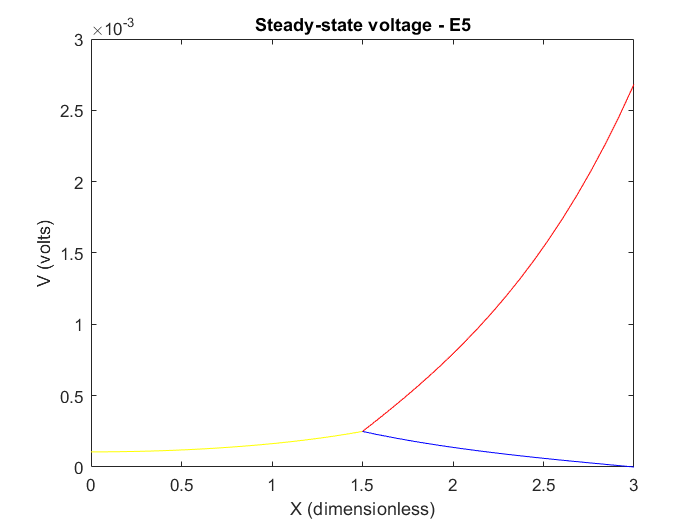

b(1) = 0; b(2) = rl21*iapp;
A_a(3,:) = A(3,:);
x_a=A_a\b;

y1 = linspace(0, l1, 20);
y21 = linspace(l1, l21, 20);
y22 = linspace(l1, l22, 20);
v1 = x_a(1)*exp(-y1) + x_a(2)*exp(y1);
v21 = x_a(3)*exp(-y21) + x_a(4)*exp(y21);
v22 = x_a(5)*exp(-y22) + x_a(6)*exp(y22);
plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
xlabel('X (dimensionless)');
ylabel('V (volts)');
title('Steady-state voltage - E5');

(d)         ${\left(\frac{d}{\mathrm{d}X}V_{22} \right)}_{X=L_{22} } ={\left(r_i \lambda_c \right)}_{22} I_{\textrm{app}}$ ;    $-A_{22} e^{-L_{22} } +B_{22} e^{-L_{22} } ={\left(r_i \lambda_c \right)}_{22} I_{\textrm{app}} \;\;\;------\to \left({3^{\prime } }^{\prime } \right)$

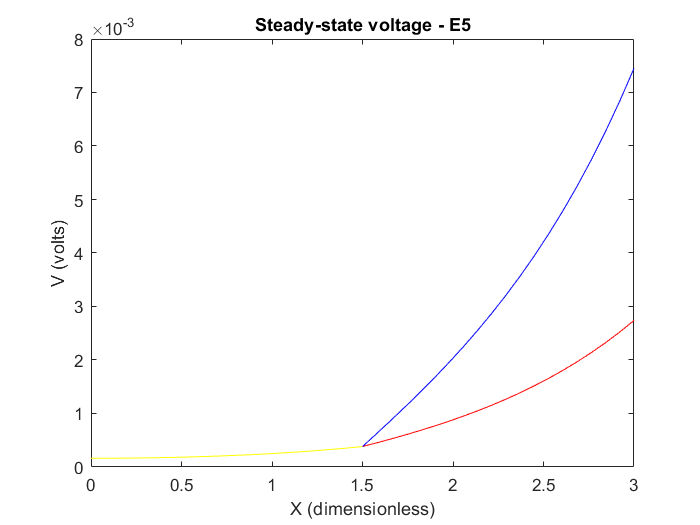

b(3) = rl22*iapp;
A_a(3,:) = [0 0 0 0 -exp(-l22) exp(l22)];
x_a=A_a\b;

y1 = linspace(0, l1, 20);
y21 = linspace(l1, l21, 20);
y22 = linspace(l1, l22, 20);
v1 = x_a(1)*exp(-y1) + x_a(2)*exp(y1);
v21 = x_a(3)*exp(-y21) + x_a(4)*exp(y21);
v22 = x_a(5)*exp(-y22) + x_a(6)*exp(y22);
plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
xlabel('X (dimensionless)');
ylabel('V (volts)');
title('Steady-state voltage - E5');

The positive right-hand sides of $\frac{dV}{dx} \quad \text{for} \quad x = \frac{L}{21} \quad \text{and} \quad x = \frac{L}{22}
$ � in Figures 2(c) and 2(d) indicate that the membrane voltage gradient is positive at the rightmost nodes of the daughter branches. This positive gradient signifies that the daughter branches are transmitting an electrical impulse to another neuron or branch, facilitating efficient impulse transmission from the parent branch to the daughter branches. Consequently, the membrane voltages at the boundaries of the daughter branches are higher than those at the boundary of the parent branch. Additionally, as the electrical distance from the node increases along the daughter branches, their membrane voltages also increase, as evident from the plots in Figures 2(c) and 2(d).

## Question 06

%Q6
d21 = 47.2470e-4;       % E9 cm
d22 = d21;               % E9 cm

l1 = 1.5;			% dimensionless
l21 = 3.0;			% dimensionless
l22 = 3.0;			% dimensionless

% Electrical properties of compartments

Rm = 6e3;			% Ohms cm^2
Rc = 90;			% Ohms cm
Rs = 1e6;			% Ohms

c1 = 2*(Rc*Rm)^(1/2)/pi;

rl1 = c1*d1^(-3/2);		% Ohms
rl21 = c1*d21^(-3/2);		% Ohms
rl22 = c1*d22^(-3/2);		% Ohms


% Applied current

iapp = 1e-9; 	% Amps

% Coefficient matrices

A = [1 -1 0 0 0 0;
     0 0 exp(-l21) exp(l21) 0 0;
     0 0 0 0 exp(-l22) exp(l22);
     exp(-l1) exp(l1) -exp(-l1) -exp(l1) 0 0;
     0 0 exp(-l1) exp(l1) -exp(-l1) -exp(l1);
     -exp(-l1) exp(l1) rl1*exp(-l1)/rl21 -rl1*exp(l1)/rl21 rl1*exp(-l1)/rl22 -rl1*exp(-l1)/rl22];

b = [rl1*iapp 0 0 0 0 0]';

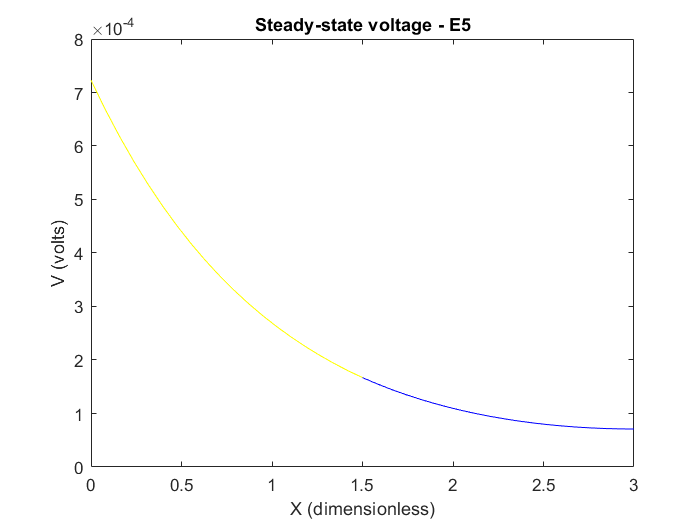

A_1=A;
A_1(2,:)=[0 0 -exp(-l21) exp(l21) 0 0];
A_1(3,:) = [0 0 0 0 -exp(-l22) exp(l22)];
x_a=A_1\b;

y1 = linspace(0, l1, 20);
y21 = linspace(l1, l21, 20);
y22 = linspace(l1, l22, 20);
v1 = x_a(1)*exp(-y1) + x_a(2)*exp(y1);
v21 = x_a(3)*exp(-y21) + x_a(4)*exp(y21);
v22 = x_a(5)*exp(-y22) + x_a(6)*exp(y22);
plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
xlabel('X (dimensionless)');
ylabel('V (volts)');
title('Steady-state voltage - E5');

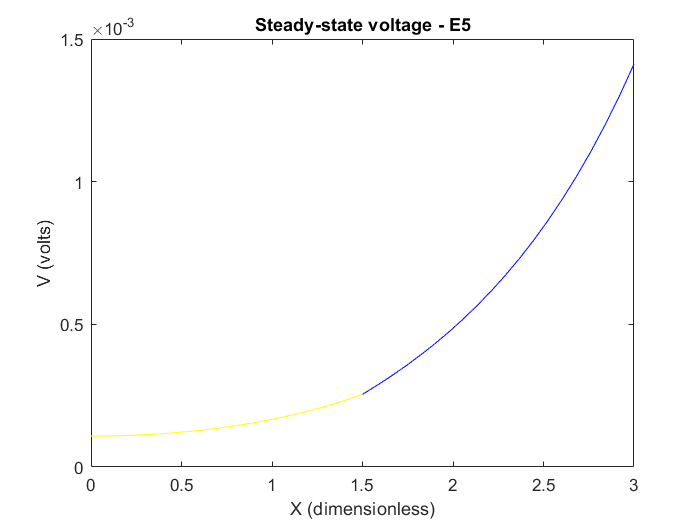

A_2=A;
b_2=b;

A_2(2,:)=[0 0 -exp(-l21) exp(l21) 0 0];
A_2(3,:) = [0 0 0 0 -exp(-l22) exp(l22)];
b_2(1) = 0; b_2(2) = rl21*iapp;
b_2(3) = rl22*iapp;
x_a=A_2\b_2;

y1 = linspace(0, l1, 20);
y21 = linspace(l1, l21, 20);
y22 = linspace(l1, l22, 20);
v1 = x_a(1)*exp(-y1) + x_a(2)*exp(y1);
v21 = x_a(3)*exp(-y21) + x_a(4)*exp(y21);
v22 = x_a(5)*exp(-y22) + x_a(6)*exp(y22);
plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
xlabel('X (dimensionless)');
ylabel('V (volts)');
title('Steady-state voltage - E5');

Comparing these graphs to 2(b) and 2(d), it appears that the graphs in 2(c) and 2(d) are continuously differentiable, while the previous graphs are not. This continuous differentiability, particularly in scenario 2(d), contributes to the minimal potential difference and ensures equal transmission of electrical impulses to both branches.